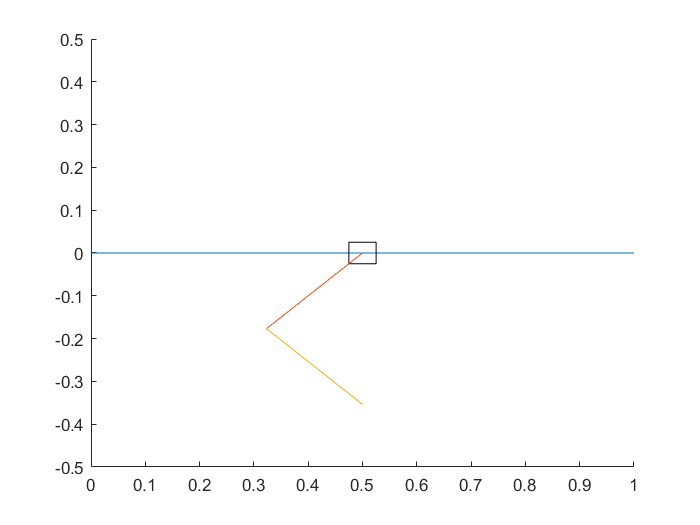

TRACK_LENGTH = 1;
CART_WIDTH = 0.05;
CART_HEIGHT = 0.05;

T_motor = 1; % in N . m
r_pulley = 0.05; % in m


l = 0.25;

theta_1 = pi/4;
ang_vel_1 = 0;
ang_accel_1 = 0;

theta_2 = -pi/4;
ang_vel_2 = 0;
ang_accel_2 = 0;

p_cart = 0.5;
v_cart = 0;
a_cart = 0;

clf
hold on
% Plot Track
plot([0 TRACK_LENGTH], [0 0])
% Plot Cart
rectangle('Position',[p_cart-CART_WIDTH/2 0-CART_HEIGHT/2 CART_WIDTH CART_HEIGHT])
% Plot Bar 1
bar_1_x = p_cart-sin(theta_1)*l;
bar_1_y = 0-cos(theta_1)*l;
plot([p_cart bar_1_x], [0 bar_1_y])
% Plot Bar 2
plot([bar_1_x bar_1_x-sin(theta_2)*l], [bar_1_y bar_1_y-cos(theta_2)*l])

axis([0 1 -0.5 0.5])
hold off